***Image Processing***

The image is just a specially formatted matrix.

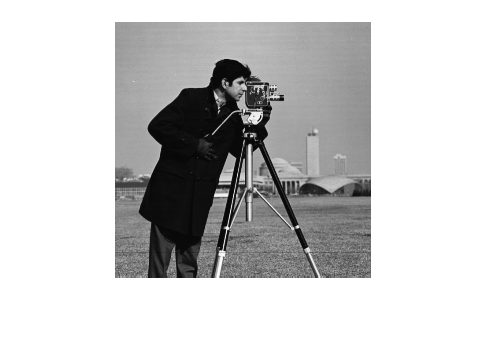

% Read in a built-in/test image
img = imread('cameraman.tif');

% Show image
imshow(img)

% See entries of the matrix representing this image
img

img = 256×256 uint8 matrix
   156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166
   160   154   157   158   157   159   158   158   158   160   155   156   159   158   160   157   165   159   161   158   162   162   161   163   159   162   164   163   164   165   169   164   163   165   161   163   165   168   167   165   164   163   169   169   169   170   170   169   170   170
   156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166
   160   154   157   158   157   159   158   158   158   160   155   1

*% Each pixel is a matrix entry - which is required to be an integer between 0 and 256. *

*% Compute the transpose of the matrix stored in the variable *`img`* (which corresponds to the image above), and display the same. Use the *`imshow`* command as used above.* 

% Transpose the matrix
img_transpose = img.'

img_transpose = 256×256 uint8 matrix
   156   160   156   160   156   155   156   159   158   155   154   152   157   151   156   157   154   151   153   152   154   155   151   150   153   154   162   158   161   158   154   152   154   155   159   155   156   152   155   160   157   157   155   160   153   158   159   162   157   160
   159   154   159   154   153   155   153   159   155   154   157   150   153   154   157   158   154   153   155   154   157   153   151   151   154   154   157   155   157   159   154   155   155   158   158   158   159   156   156   158   156   157   156   156   159   160   163   160   160   160
   158   157   158   157   155   155   157   156   158   157   157   155   156   157   157   159   156   157   154   152   155   155   153   155   151   155   155   156   158   163   156   155   156   160   157   156   157   150   153   157   160   157   157   158   156   160   165   160   156   160
   155   158   155   158   159   157   156   158   154   158

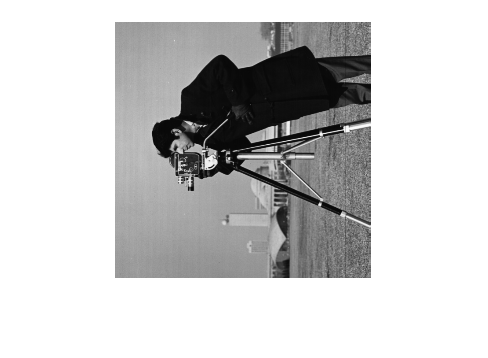

% Display transposed image
imshow(img_transpose)

% The transpose image is the same as the image of original image, but it is flipped about y axis and  turned to to the left for 90 degree. 
% So, the original image is flipped about the main diagonal.

*% *Here are some other operations 

% Vectorizing a matrix

% (the result is a column vector)
img_vec = img(:)

img_vec = 65536×1 uint8 column vector
   156
   160
   156
   160
   156
   155
   156
   159
   158
   155


% Display the size of the original matrix
size(img)

ans =    256   256


% ... and the size of the vectorized version
size(img_vec)

ans =        65536           1


- **Computing inner products**

            Let's use inner products to help us decide whether an image is oriented the right side up!

% Some pre-processing
img_vec = double(img_vec);

% For normalization
norm_const = norm(img_vec)^2

norm_const = 1.1785e+09

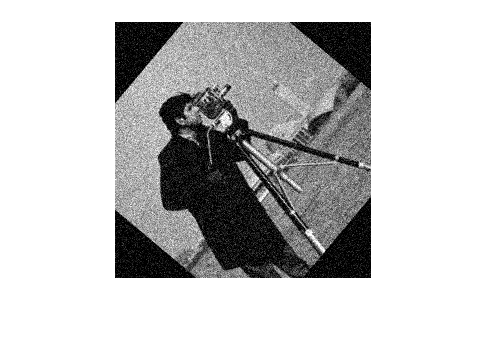

% Here is a rotated image
angle = 50;     % rotation angle (in degrees)
img_rot = imrotate(img, angle, 'bilinear', 'crop');

% Let's add some noise (measurement errors)
img_rot = imnoise(img_rot);

% Display rotated image
imshow(img_rot)

% some pre-processing
img_rot = double(img_rot(:));

% The dot product of the original image and the
% rotated version?
dot(img_vec, img_rot)/norm_const

ans = 0.6994

*==========================================================*

*It will be the largest value when the angle is 2n*pi because dot product is multiplication of the magnitudes of 2 vectors times cos(angle), and the maximum of cos( angle) is 1 when angle is 2n*pi where n is an integer.*

*==========================================================*

- Adding/subtracting a scalar to a matrix

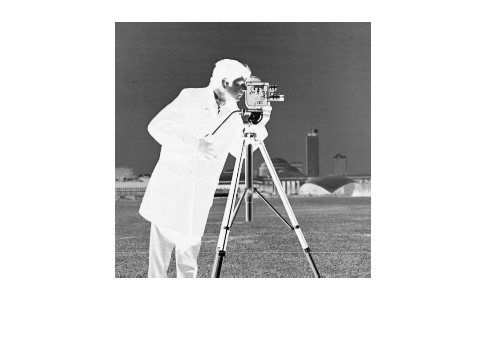

% Subtract each "pixel" from 256
img_neg = uint8(256) - img;

% Display image
imshow(img_neg)

*==========================================================*

*The color of black turns into white, and the color of white turns into black.*

*==========================================================*

- Compute weighted (linear) combinations using  'unit8'

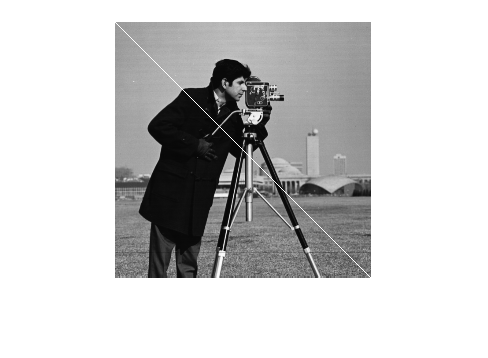

% Linear combination
% Compute a weighted sum of two matrices
img_mod = img + 256*eye(size(img), 'uint8');
imshow(img_mod)

*==========================================================*

* There shows white diagonal straight line from the top left to the bottom right. *

* 'unit 8' give white color having 256 on the main diagonal on the matrix.*

*==========================================================*

- Directly modify entries of a matrix/vector 

% Change third entry of vector u
u(3) = -22/7

u =          0         0   -3.1429


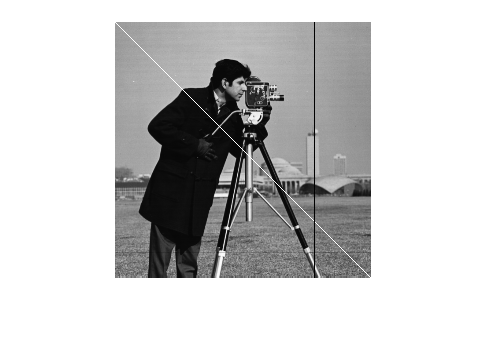

% Change column #200 of a matrix
img_mod(:,200) = 0;
imshow(img_mod)

*==========================================================*

*The black straight line is added vertically at the location of 200th comuns to the previous image.*

*==========================================================*

### Solving Linear Systems

Here is the linear system 


$$\begin{array}{rcl}
x+2y+z & = & 1 \\
3x+7y+3z & = & 1 \\
-2x-3y-4z & = & -1.
\end{array}$$


% Construct augmented matrix
aug_mat = [ 1  2  1  1; ...
            3  7  3  1; ...
           -2 -3 -4 -1]

aug_mat =      1     2     1     1
     3     7     3     1
    -2    -3    -4    -1


*==========================================================*

*Elimination Matrices*

*==========================================================*

*Construct the first two elimination matrices (corresponding to the first two steps of Gaussian elimination) below.* 

E_21 = [1 0 0;-3 1 0;0 0 1]

E_21 =      1     0     0
    -3     1     0
     0     0     1


E_31 = [1 0 0;0 1 0; 2 0 1]

E_31 =      1     0     0
     0     1     0
     2     0     1


*==========================================================*

Multiplying (from the left) by an elimination matrix performs one step of elimination. 

% first step of elimination
after_step1 = E_21*aug_mat

after_step1 =      1     2     1     1
     0     1     0    -2
    -2    -3    -4    -1


*==========================================================*

* Performing Elimination*

*==========================================================*

*Perform the next step of elimination by multiplying with the elimination matrix *$E_{31}$*. *

% next step of elimination
after_step2 = E_31*after_step1

after_step2 =      1     2     1     1
     0     1     0    -2
     0     1    -2     1


*==========================================================*

Suppose the coefficient matrix and right hand side are given respectively by 


$$A = \pmatrix{1 & 2 & 1 \cr
3 & 7 & 3 \cr
-2 & -3 & -4}, \qquad \qquad 

\vec{b} = \pmatrix{1 \cr 1 \cr -1}, $$


which are coded in Matlab as follows

% Coefficient matrix
A = [ 1  2  1 ; ...
      3  7  3 ; ...
     -2 -3 -4 ]

A =      1     2     1
     3     7     3
    -2    -3    -4


% Right hand side
b = [1; 1; -1]

b =      1
     1
    -1


Solving the system using the backslash (`\`) command.

% Solve system
soln = A\b

soln =     6.5000
   -2.0000
   -1.5000


Another way to solve this system is using the Matrix inverse.

% Compute inverse of the matrix A
A_inv = inv(A)

A_inv =     9.5000   -2.5000    0.5000
   -3.0000    1.0000         0
   -2.5000    0.5000   -0.5000


% Find solution to system using the matrix inverse
soln_using_inv = A_inv*b

soln_using_inv =     6.5000
   -2.0000
   -1.5000


*Note**: In practice, use the *`\`* command to solve a system!*

### LU Factorization

Consider the matrix from Question #5 of the HW set: 


$$A = \pmatrix{2 & 2 & 2 \cr
4 & 7 & 7 \cr
6 & 18 & 22}.$$


Matlab allows us to compute the LU factorization of this matrix as follows:

% Construct matrix A
A = [ 2  2  2 ; ...
      4  7  7 ; ...
      6 18 22 ];

% Compute LU factorization
[L, U, P] = lu(A, 'matrix')

L =     1.0000         0         0
    0.6667    1.0000         0
    0.3333    0.8000    1.0000


U =     6.0000   18.0000   22.0000
         0   -5.0000   -7.6667
         0         0    0.8000


P =      0     0     1
     0     1     0
     1     0     0


*Note**: Matlab almost always performs row exchanges (for numerical stability) - so pen/paper answer may be different from the answer above.*

*Note**:  To be consistent with pen/paper work (Not recommended)*

% (Not recommended) Alternate LU factorization
[L, U] = lu(sparse(A), 0);
L = full(L)

L =      1     0     0
     2     1     0
     3     4     1


U = full(U)

U =      2     2     2
     0     3     3
     0     0     4


#### Why is LU Factorization Useful?

Suppose we are solving 10,000 linear systems with the same $1000\times 1000$ coefficient matrix $A$. 

Let's compare the cost of doing this naively using the `\` operator versus using LU factorization.

% Create (random) 1000 x 1000 coefficient matrix
A = randn(1000);

% Create 10,000 rhs vectors (store as columns of a 1000 x 10,000 matrix
bvecs = randn(1000,10000);

% Let's solve these systems using \
tic    % Start counting time
for idx = 1:1000
    x = A\bvecs(:,idx);
end
toc    % This displays the time taken

Elapsed time is 18.243364 seconds.


% Now let's do this using LU factorization
% Compute and store LU factorization
dA = decomposition(A,'lu');

tic    % Start counting time
for idx = 1:1000
    x = dA\bvecs(:,idx);
end
toc    % This displays the time taken

Elapsed time is 0.466317 seconds.


*==========================================================*

* Comparing cost of Elimination vs LU Factorization*

*Using LU Factorization is much faster.*

*==========================================================*

### Reduced Row Echelon Form and Nullspace

Consider the system of equations 


$$\begin{array}{rcl}
x_1+2x_2+x_3+2x_4 & = & 3 \\
2x_1+4x_2+x_3+3x_4 & = & 4 \\
3x_1+6x_2+x_3+4x_4 & = & 5.
\end{array}$$


*==========================================================*

*Reduced Row Echelon Form*

*==========================================================*

*Construct the coefficient matrix and use the rref() command to find its reduced row echelon form*

% Write your answer here...
% Construct the coefficient matrix
A = [ 1  2  1  2  ; ...
      2  4  1  3  ; ...
      3  6  1  4  ];

% Reduced row echelon form of A
rref(A)

ans =      1     2     0     1
     0     0     1     1
     0     0     0     0


Here are some other operations than can be performed...

- Finding the rank of the matrix

% Rank of the matrix // the number of pivot
rank(A)

ans = 2

- Finding (a basis for) the nullspace of the matrix

%  Basis for the nullspace of A
basis_null = null(A, 'rational')

basis_null =     -2    -1
     1     0
     0    -1
     0     1
